# **Two storey steel moment frame with W-sections for displacement-controlled sensitivity analysis**

clc; clear;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

[OpenSeesMatlab] Model summary
  Nodes: 6
  Beam elements: 6


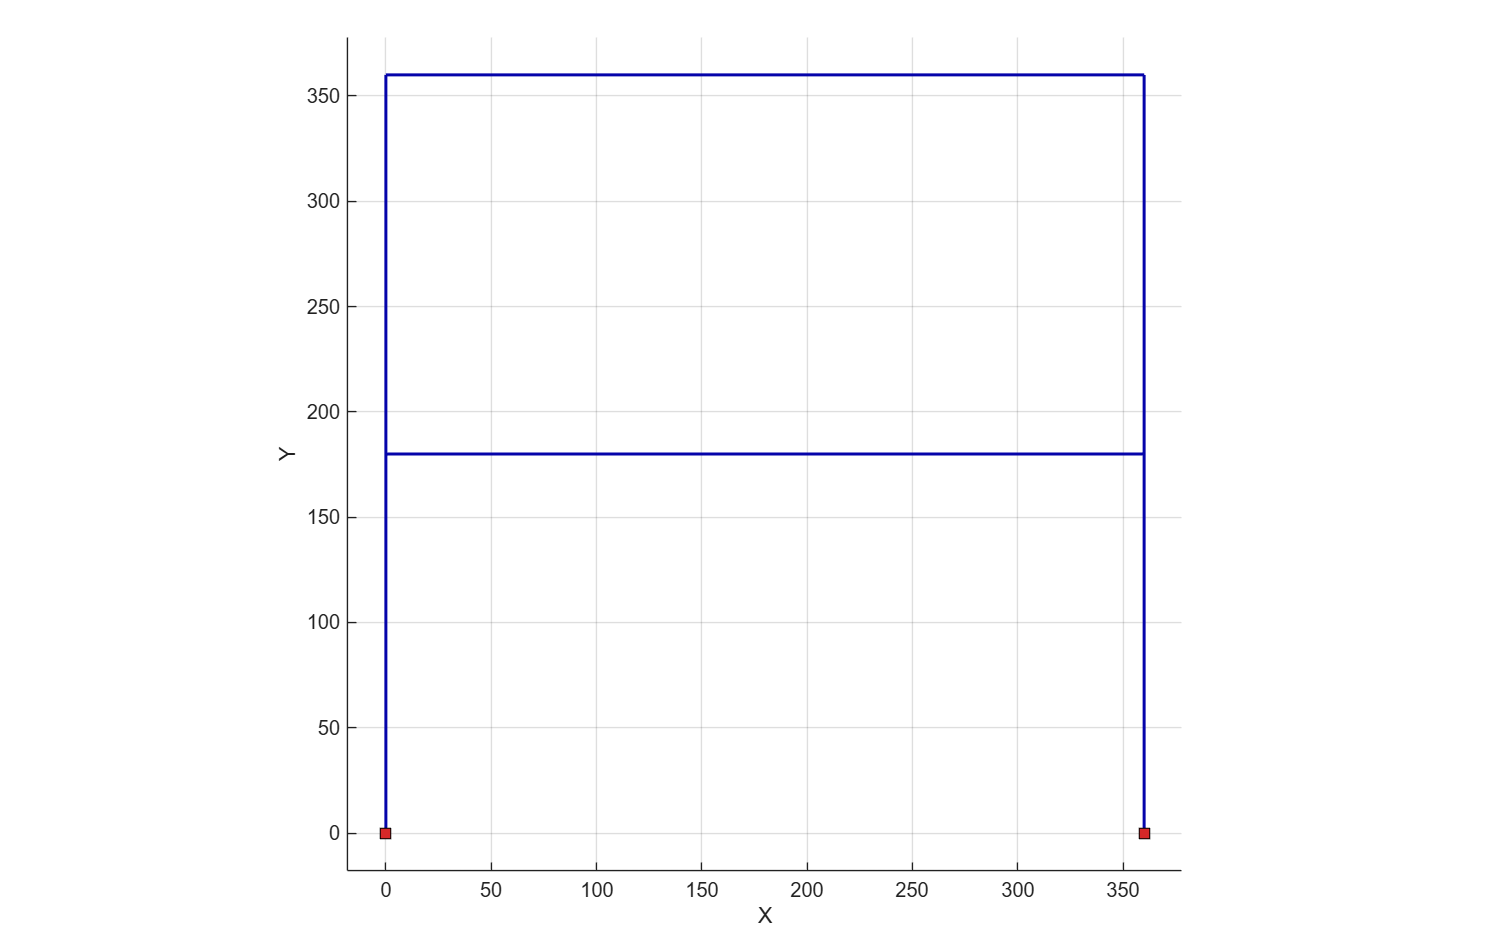

inch = 1.0;
kip = 1.0;
ft = 12 * inch;
ksi = kip / inch^2;

ops.wipe();
ops.model('basic', '-ndm', 2, '-ndf', 3);

ops.node(1, 0.0, 0.0);
ops.node(2, 30 * ft, 0.0);
ops.node(3, 0.0, 15 * ft);
ops.node(4, 30 * ft, 15 * ft);
ops.node(5, 0.0, 30 * ft);
ops.node(6, 30 * ft, 30 * ft);

ops.fix(1, 1, 1, 1);
ops.fix(2, 1, 1, 1);

matTag = 1;
Fy = 50.0 * ksi;
Es = 29000.0 * ksi;
b = 1 / 100;

ops.uniaxialMaterial('Steel01', matTag, Fy, Es, b);

colSecTag = 1;
beamSecTag = 2;

W18x76 = [18.2 * inch, 0.425 * inch, 11.04 * inch, 0.68 * inch];
W14x90 = [14.02 * inch, 0.44 * inch, 14.52 * inch, 0.71 * inch];

ops.section('WFSection2d', colSecTag, matTag, W14x90(1), W14x90(2), W14x90(3), W14x90(4), 20, 4);
ops.section('WFSection2d', beamSecTag, matTag, W18x76(1), W18x76(2), W18x76(3), W18x76(4), 20, 4);

colTransTag = 1;
beamTransTag = 2;
ops.geomTransf('Corotational', colTransTag);
ops.geomTransf('Linear', beamTransTag);

colIntTag = 1;
beamIntTag = 2;
nip = 5;
ops.beamIntegration('Lobatto', colIntTag, colSecTag, nip);
ops.beamIntegration('Lobatto', beamIntTag, beamSecTag, nip);

ops.element('forceBeamColumn', 10, 1, 3, colTransTag, colIntTag, '-mass', 0.0);
ops.element('forceBeamColumn', 11, 3, 5, colTransTag, colIntTag, '-mass', 0.0);
ops.element('forceBeamColumn', 12, 2, 4, colTransTag, colIntTag, '-mass', 0.0);
ops.element('forceBeamColumn', 13, 4, 6, colTransTag, colIntTag, '-mass', 0.0);
ops.element('forceBeamColumn', 14, 3, 4, beamTransTag, beamIntTag, '-mass', 0.0);
ops.element('forceBeamColumn', 15, 5, 6, beamTransTag, beamIntTag, '-mass', 0.0);

ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);

ops.parameter(1);
ops.parameter(2);
ops.parameter(3);
for ele = [10, 11, 12, 13]
    ops.addToParameter(1, 'element', ele, 'E');
    ops.addToParameter(2, 'element', ele, 'fy');
    ops.addToParameter(3, 'element', ele, 'b');
end

figure;
opsMAT.vis.plotModel();

run_gravity_analysis(10, ops);

ops.load(3, 1/3, 0.0, 0.0);
ops.load(5, 2/3, 0.0, 0.0);

max_disp = 20 * inch;
paramTags = ops.getParamTags();
pushover_output = run_sensitivity_pushover_analysis(5, [1, 2], 1, (1/25) * inch, max_disp, paramTags, false, ops);

Analysis elapsed time is 0.377 seconds.


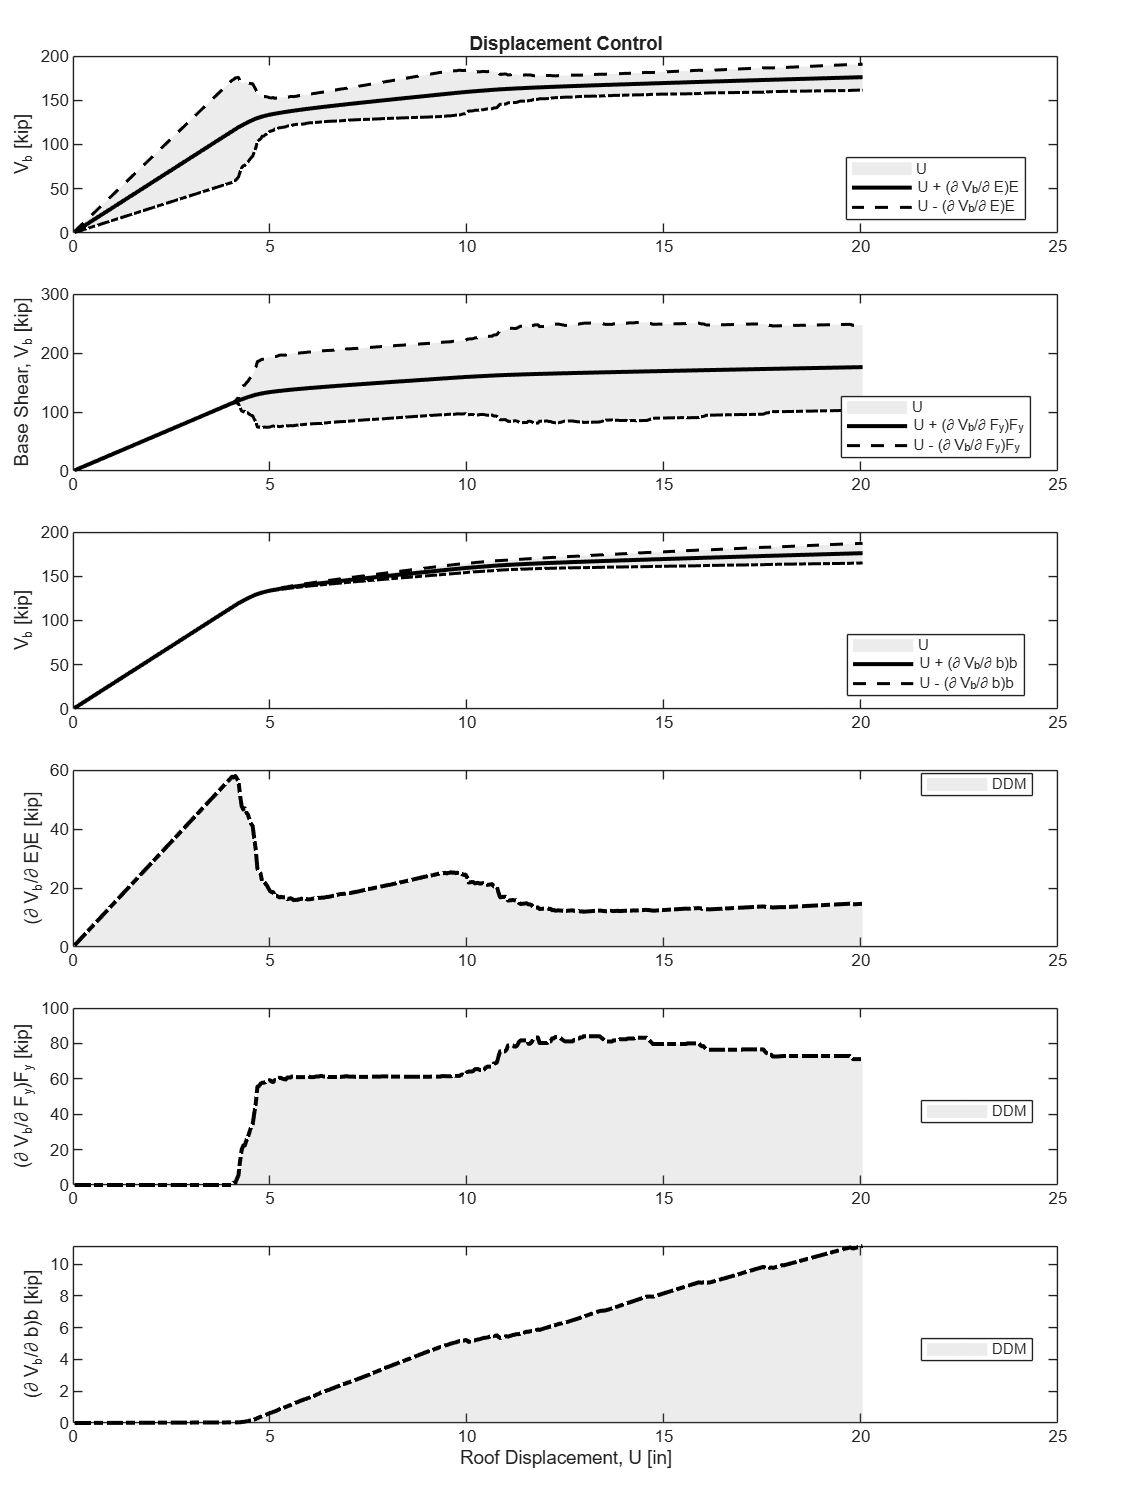

figure;
rows = numel(paramTags) * 2;
tiledlayout(rows, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
ParamSym = {'E', 'F_y', 'b'};
ParamVars = [Es, Fy, b];

for s = 1:rows
    nexttile;
    plot_params(max_disp);

    if s <= numel(paramTags)
        sens = pushover_output.(sprintf('sensLambda_%d', s));
        plot(pushover_output.disp, pushover_output.force, '-k', 'LineWidth', 2.0); hold on;
        plot(pushover_output.disp, pushover_output.force + sens * ParamVars(s), '--k', 'LineWidth', 1.5);
        plot(pushover_output.disp, pushover_output.force - sens * ParamVars(s), '-.k', 'LineWidth', 1.5);
        fill([pushover_output.disp; flipud(pushover_output.disp)], ...
             [pushover_output.force + sens * ParamVars(s); flipud(pushover_output.force - sens * ParamVars(s))], ...
             [0.5 0.5 0.5], 'FaceAlpha', 0.15, 'EdgeColor', 'none');
        uistack(findobj(gca, 'Type', 'line'), 'top');
        if s == 1
            title('Displacement Control');
        end
        if s == 2
            ylabel('Base Shear, V_b [kip]');
        else
            ylabel('V_b [kip]');
        end
        legend({'U', ...
                sprintf('U + (\\partial V_b/\\partial %s)%s', ParamSym{s}, ParamSym{s}), ...
                sprintf('U - (\\partial V_b/\\partial %s)%s', ParamSym{s}, ParamSym{s})}, ...
                'Location', 'best');
    else
        k = s - numel(paramTags);
        sens = pushover_output.(sprintf('sensLambda_%d', k));
        plot(pushover_output.disp, sens * ParamVars(k), '-.k', 'LineWidth', 2.0); hold on;
        fill([pushover_output.disp; flipud(pushover_output.disp)], ...
             [sens * ParamVars(k); zeros(size(sens))], ...
             [0.5 0.5 0.5], 'FaceAlpha', 0.15, 'EdgeColor', 'none');
        uistack(findobj(gca, 'Type', 'line'), 'top');
        ylabel(sprintf('(\\partial V_b/\\partial %s)%s [kip]', ParamSym{k}, ParamSym{k}));
        if s == rows
            xlabel('Roof Displacement, U [in]');
        end
        legend({'DDM'}, 'Location', 'best');
    end
end

set(gcf, 'Position', [100, 100, 900, 1200]);

function run_gravity_analysis(steps, ops)
    ops.wipeAnalysis();
    ops.system('BandGeneral');
    ops.numberer('RCM');
    ops.constraints('Transformation');
    ops.test('NormDispIncr', 1.0E-12, 10, 3);
    ops.algorithm('Newton');
    ops.integrator('LoadControl', 1 / steps);
    ops.analysis('Static');
    ops.analyze(steps);
    ops.loadConst('-time', 0.0);
    ops.wipeAnalysis();
end

function outputs = run_sensitivity_pushover_analysis(ctrlNode, baseNodes, dof, Dincr, max_disp, SensParam, IOflag, ops)
    ops.wipeAnalysis();
    start_time = tic;
    ops.loadConst('-time', 0.0);

    testType = 'NormDispIncr';
    tolInit = 1.0E-8;
    iterInit = 10;
    algorithmType = 'Newton';

    ops.system('BandGeneral');
    ops.constraints('Transformation');
    ops.numberer('RCM');
    ops.test(testType, tolInit, iterInit);
    ops.algorithm(algorithmType);
    ops.integrator('DisplacementControl', ctrlNode, dof, Dincr);
    ops.analysis('Static');
    ops.sensitivityAlgorithm('-computeAtEachStep');

    if IOflag
        fprintf('Single Pushover: Push node %d to %.6g.\n', ctrlNode, max_disp);
    end

    outputs.time = [];
    outputs.disp = [];
    outputs.force = [];

    for i = 1:numel(SensParam)
        outputs.(sprintf('sensLambda_%d', SensParam(i))) = [];
    end

    currentDisp = ops.nodeDisp(ctrlNode, dof);
    ok = 0;

    while ok == 0 && currentDisp < max_disp
        ops.reactions();
        ok = ops.analyze(1);
        currentDisp = ops.nodeDisp(ctrlNode, dof);

        if IOflag
            fprintf('Current displacement ==> %.6g\n', currentDisp);
        end

        if ok ~= 0
            fprintf('\n==> Trying relaxed convergence...\n');
            ops.test(testType, tolInit / 0.01, iterInit * 50);
            ok = ops.analyze(1);
            ops.test(testType, tolInit, iterInit);
        end

        if ok ~= 0
            fprintf('\n==> Trying Newton with initial then current...\n');
            ops.test(testType, tolInit / 0.01, iterInit * 50);
            ops.algorithm('Newton', '-initialThenCurrent');
            ok = ops.analyze(1);
            ops.algorithm(algorithmType);
            ops.test(testType, tolInit, iterInit);
        end

        if ok ~= 0
            fprintf('\n==> Trying ModifiedNewton with initial...\n');
            ops.test(testType, tolInit / 0.01, iterInit * 50);
            ops.algorithm('ModifiedNewton', '-initial');
            ok = ops.analyze(1);
            ops.algorithm(algorithmType);
            ops.test(testType, tolInit, iterInit);
        end

        baseShear = 0.0;
        ops.reactions();
        for node = baseNodes
            baseShear = baseShear - ops.nodeReaction(node, dof);
        end

        outputs.time(end+1, 1) = ops.getTime();
        outputs.disp(end+1, 1) = ops.nodeDisp(ctrlNode, dof);
        outputs.force(end+1, 1) = baseShear;

        for i = 1:numel(SensParam)
            tag = SensParam(i);
            field = sprintf('sensLambda_%d', tag);
            outputs.(field)(end+1, 1) = ops.sensLambda(1, tag);
        end
    end

    elapsed = toc(start_time);
    fprintf('Analysis elapsed time is %.3f seconds.\n', elapsed);
end

function plot_params(max_disp)
    ax = gca;
    ax.Layer = 'top';
    xlim([0.0, max_disp]);
    grid on;
    ax.GridColor = [0.75 0.75 0.75];
    ax.GridAlpha = 0.75;
    ax.LineWidth = 0.75;
    ax.TickDir = 'in';
end